# Sample 5-5

## 周波数解析

多変量畳み込み

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Fourier analysis

Multivariate convolution

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 準備

(Preparation)

close all

### サンプル画像$\{u[\mathbf{n}]\}_\mathbf{n}
$の準備

(Preparation of sample image $\{u[\mathbf{n}]\}_\mathbf{n}
$)

% Reading original image
u = im2double(imread('cameraman.tif'));
figure(1)
imshow(u)

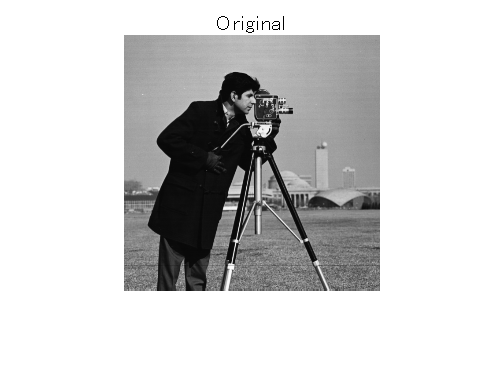

title('Original')

### 線形シフト不変システムのインパルス応答 $\{h[\mathbf{n}]\}_\mathbf{n}
$ 

(Impulse response of a linear shift-invariant system $\{h[\mathbf{n}]\}_\mathbf{n}
$

% Impulse response h[n]
ftype = "gaussian";
h = rot90(fspecial(ftype),2);

### 線形シフト不変システムの出力応答$\{v[\mathbf{n}]\}_\mathbf{n}
$ 

(The linear shift-invariant system response $\{v[\mathbf{n}]\}_\mathbf{n}
$)

畳み込み演算 (Convolution)

        
$$\{v[\mathbf{n}]\}_\mathbf{n}=\{h[\mathbf{n}]\}_\mathbf{n} \ast \{u[\mathbf{n}]\}_\mathbf{n} = \sum_{\mathbf{k}\in\Omega\subset\mathbb{Z}^2}u[\mathbf{k}]\{h[\mathbf{n}-\mathbf{k}]\}_\mathbf{n}
$$


% Output v[n]
v = imfilter(u,h,'conv','full');

### 入力信号 $\{u[\mathbf{n}]\}_{\mathbf{n}}
$ のスペクトル

(Spectrum of input signal $\{u[\mathbf{n}]\}_{\mathbf{n}}
$)

        
$$U\left(e^{\j\mathbf{\omega}^T}\right)= \sum_{\mathbf{n}\in\mathbb{Z}^2}u[\mathbf{n}]e^{-\j\mathbf{\omega}^T n},\ \mathbf{\omega}\in\mathbb{R}^2$$


DFT(FFT)によるDSFTの周波数サンプル計算 (Frequency sampling of DSFT by DFT (FFT))

        
$$U[\mathbf{k}] = \left.U\left(e^{j\mathbf{\omega}^T}\right)\right|_{\mathbf{\omega}=2\pi \mathbf{Q}^{-T}\mathbf{k}},\ \mathbf{k}\in\mathcal{N}(\mathbf{Q}^T)$$


関数FFTNを利用．(The function FFTN is used.)

% Setting the number of frequency sample points in [0,2π)^2
nPoints = pow2(nextpow2(size(u)+size(h)-1)); % The least power of two that matches the normal convolution

% Spectrum of u[n]
U = fftn(u,nPoints);

### フィルタ $\{h[\mathbf{n}]\}_\mathbf{n}
$ の周波数応答

(Frequency response of filter$\{h[\mathbf{n}]\}_\mathbf{n}
$)

        
$$H\left(e^{\j\mathbf{\omega}^T}\right)= \sum_{\mathbf{n}\in\mathbb{Z}^2}h[\mathbf{n}]e^{-\j\mathbf{\omega}^T n},\ \mathbf{\omega}\in\mathbb{R}^2$$


DFT(FFT)によるDSFTの周波数サンプル計算 (Frequency sampling of DSFT by DFT (FFT))

        
$$H[\mathbf{k}] = \left.H\left(e^{j\mathbf{\omega}^T}\right)\right|_{\mathbf{\omega}=2\pi \mathbf{Q}^{-T}\mathbf{k}},\ \mathbf{k}\in\mathcal{N}(\mathbf{Q}^T)$$


% Frequency response of h[n]
H = fftn(h,nPoints);

### 出力信号 $\{v[\mathbf{n}]\}_\mathbf{n}
$ のスペクトル

(Spectrum of input signal $\{v[\mathbf{n}]\}_\mathbf{n}
$)

        
$$V\left(e^{\j\mathbf{\omega}^T}\right)= \sum_{\mathbf{n}\in\mathbb{Z}^2}v[\mathbf{n}]e^{-\j\mathbf{\omega}^T n},\ \mathbf{\omega}\in\mathbb{R}^2$$


DFT(FFT)によるDSFTの周波数サンプル計算 (Frequency sampling of DSFT by DFT (FFT))

        
$$V[\mathbf{k}] = \left.V\left(e^{j\mathbf{\omega}^T}\right)\right|_{\mathbf{\omega}=2\pi \mathbf{Q}^{-T}\mathbf{k}},\ \mathbf{k}\in\mathcal{N}(\mathbf{Q}^T)$$


% Frequency response of v[n]
V = fftn(v,nPoints);

### スペクトルと周波数応答の表示

(Display of spectra and frequency response)

        
$$V\left(e^{\j\mathbf{\omega}^T}\right)=H\left(e^{\j\mathbf{\omega}^T}\right)U\left(e^{\j\mathbf{\omega}^T}\right)$$


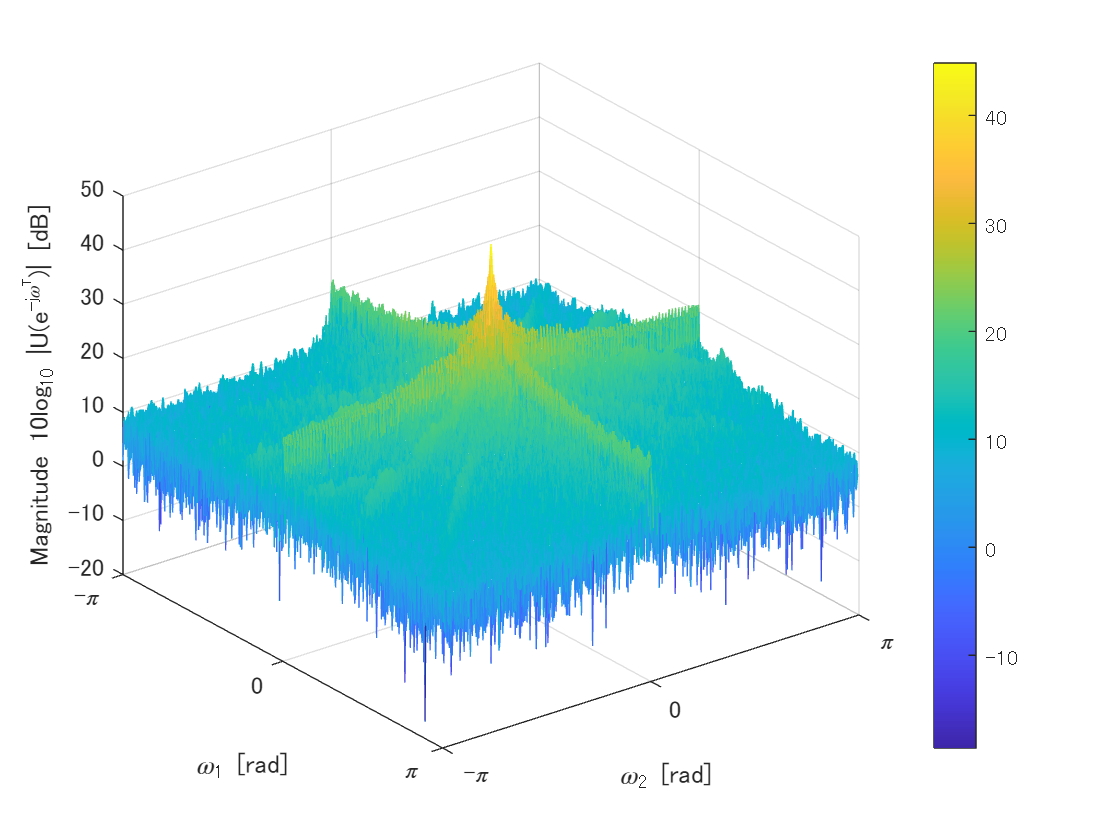

% Frequency sample points 
[w1,w2] = meshgrid(-pi:2*pi/nPoints(1):pi-2*pi/nPoints(1),-pi:2*pi/nPoints(2):pi-2*pi/nPoints(2));

% Display of spectrum U
figure(2)
mesh(w1,w2,10*log10(abs(fftshift(U))))
ax = gca;
xlabel('\omega_2 [rad]')
ylabel('\omega_1 [rad]')
zlabel('Magnitude 10log_{10} |U(e^{-j\omega^T})| [dB]')
axis ij
ax.XLim = [-pi pi];
ax.XTick = [ -pi 0 pi ];
ax.XTickLabel = { '-\pi', '0', '\pi'};
ax.YLim = [-pi pi];
ax.YTick = [ -pi 0 pi ];
ax.YTickLabel = { '-\pi', '0', '\pi'};
colorbar(ax)

% Display of Freq. response H
figure(3)
mesh(w1,w2,10*log10(abs(fftshift(H))))
ax = gca;
xlabel('\omega_2 [rad]')
ylabel('\omega_1 [rad]')
zlabel('Magnitude 10log_{10} |H(e^{-j\omega^T})| [dB]')
axis ij
ax.XLim = [-pi pi];
ax.XTick = [ -pi 0 pi ];
ax.XTickLabel = { '-\pi', '0', '\pi'};
ax.YLim = [-pi pi];
ax.YTick = [ -pi 0 pi ];
ax.YTickLabel = { '-\pi', '0', '\pi'};
colorbar(ax)

% Display of Freq. response V
figure(4)
mesh(w1,w2,10*log10(abs(fftshift(V))))
ax = gca;
xlabel('\omega_2 [rad]')
ylabel('\omega_1 [rad]')
zlabel('Magnitude 10log_{10} |V(e^{-j\omega^T})| [dB]')
axis ij
ax.XLim = [-pi pi];
ax.XTick = [ -pi 0 pi ];
ax.XTickLabel = { '-\pi', '0', '\pi'};
ax.YLim = [-pi pi];
ax.YTick = [ -pi 0 pi ];
ax.YTickLabel = { '-\pi', '0', '\pi'};
colorbar(ax)

### 線形シフト不変システムの解析

(Analysis of linear shift-invariant systems)

周波数応答(Frequency response)の表示

        
$$H\left(e^{\j\mathbf{\omega}^T}\right)= \left.H(\mathbf{z})\right|_{\mathbf{z}=e^{\j\mathbf{\omega}^T}},\ \mathbf{\omega}\in \mathbb{R}^2$$


- 振幅応答 (Magnitude response): $|H\left(e^{\j\mathbf{\omega}^T}\right)|$

- 位相応答 (Phase response): $\angle H\left(e^{\j\mathbf{\omega}^T}\right)$

2変量周波数振幅応答の表示関数FREQZ2を利用．(Using FREQZ2, a display function for bivariate frequency magnitude responses.)

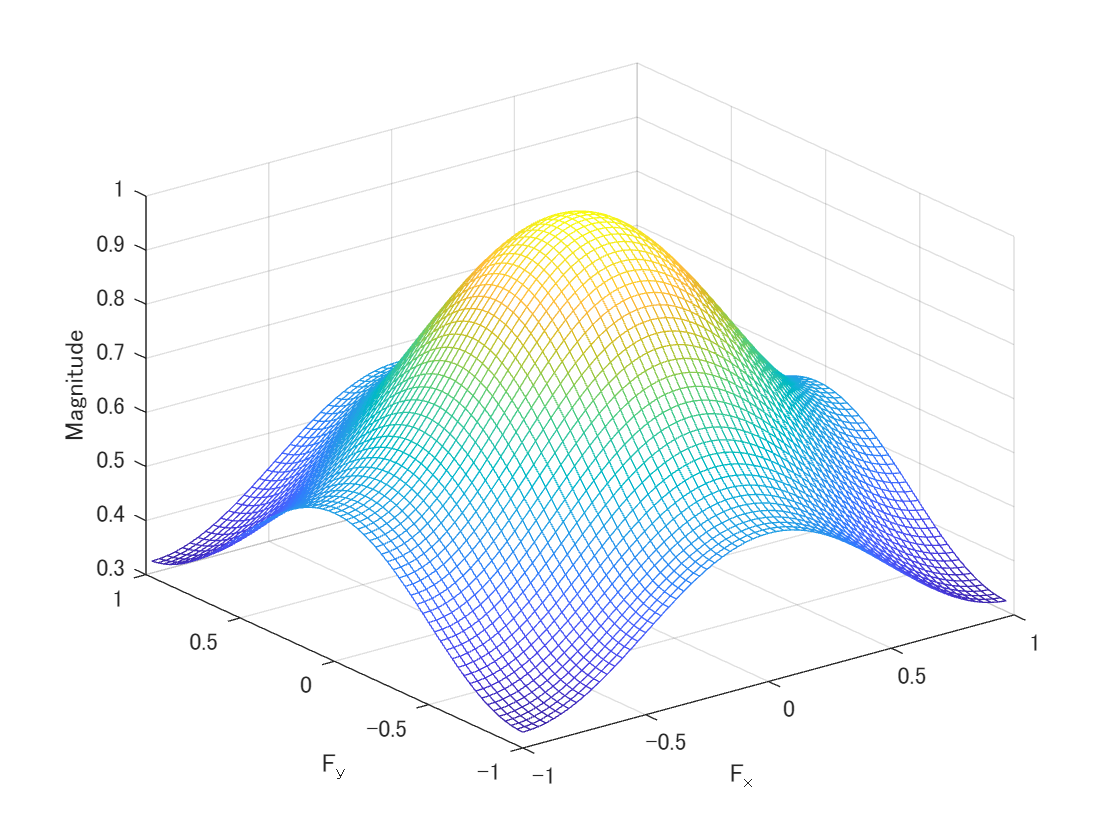

figure(5)
freqz2(h)

© Copyright, Shogo MURAMATSU, All rights reserved.